## Histogram of oriented gradients

clc;
close all;
clear variables;

### Loading files

input_file_subfolder = 'data\preprocessed\binarized\training';
intput_file_expension = 'bmp';

input_files = dir(input_file_subfolder + "/" +  "*." + intput_file_expension)

input_files = 435×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


### Example file

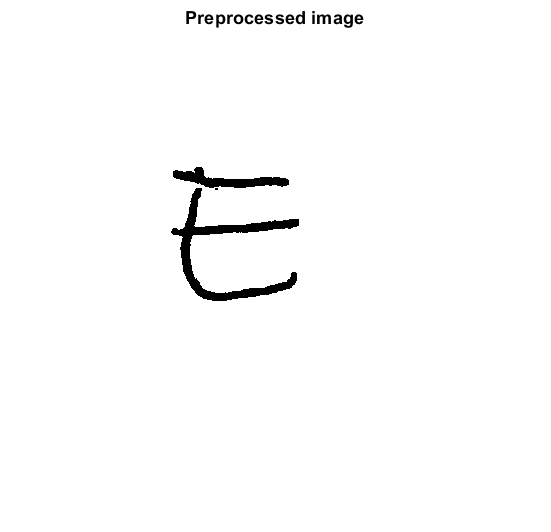

input_file = input_files(121);
file_path = input_file.folder + "\" + input_file.name;
img = imread(file_path);
figure()
imshow(img)
title('Preprocessed image')

### Feature extraction

cell_size = 48;
nbins = 4;
[featureVector, hogVisualization] = extractHOGFeatures(img, 'CellSize',[cell_size cell_size], 'NumBins',nbins);
N = size(featureVector, 2)

N = 672

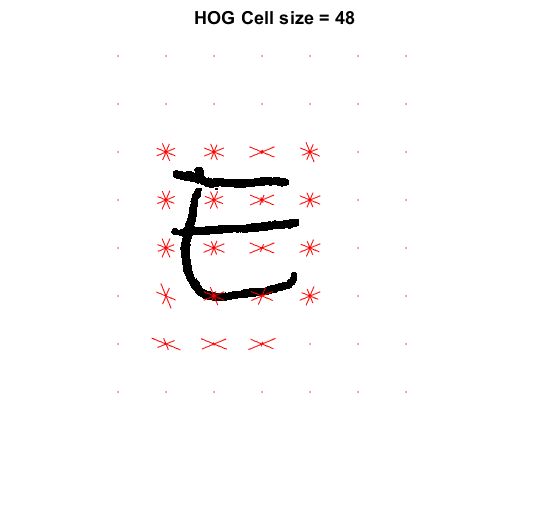

figure;
imshow(img); 
hold on;
plot(hogVisualization, 'Color', 'Red');
title("HOG Cell size = " + cell_size)

### Get training data

image_size = size(img);

training_set = Dataset(input_files, image_size, cell_size, N, nbins);

cell_size = 24;
nbins = 3

nbins = 3

training_set.resizeImages([150 150], cell_size, nbins)

ans =   Dataset with properties:

           labels: [435×1 double]
           images: [435×150×150 uint8]
       image_size: [150 150]
    hog_cell_size: 24
        hog_nbins: 3
             data: [300×435 single]
     class_labels: 'AEIOU'


num = 1

num = 1

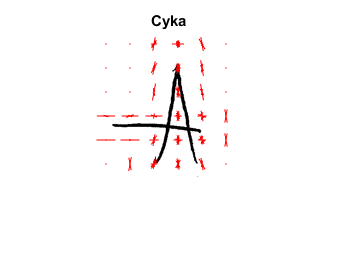

img = training_set.getImage(num);
visualization = training_set.getHOGVisualization(num);

figure;
imshow(img); 
hold on;
plot(visualization, 'Color', 'Red');
title("Cyka")

[coeff,latent,explained] = pcacov(training_set.cov);

training_set.getApriori()

ans =     0.1839
    0.2115
    0.1954
    0.2207
    0.1885
